# Polar Plot Examples using makePolarGrid

Making good looking polar plots with built-in Matlab functions isn't so easy, especially if you want to customize them. These couple of functions make it easy (hopefully).

Eric Thornhill, 2019

## Polar Plot Example 1

First define some data to plot, say a cardioid plot.

clear all
clc
theta = 0:1:360;       % Note default for these polar plot tools is degrees
r = 2 + 2*cosd(theta);

Now set up the polar grid. For this first example, will use the standard math convention with the theta=0 on the x-axis with theta increasing counter-clockwise. The makePolarGrid.m function takes in a series of argument-value pairs. See its help for a list and thier default values. For this first example only the those needed are shown.

figure(1); clf
ph = makePolarGrid(...
  'ADir',         'ccw',...    % 'clockwise'/'ccw' or 'counterclockwise'/'ccw'
  'AZeroPos',     'top',...   % initial 0deg position 'top',left','bottom','right'
  'RTicks',       0:1:5,...     % Radial ticks (inner circles)
  'RLabelFormat', '%.1f');      % Format for radial labels

Now to transform our polar (r,theta) data into the correct cartesian version so that the usual matlab plot functions can be used. The output "ph" is used as the input to polgrid2cart.m.

[px,py] = polgrid2cart(theta, r, ph);

Then plot onto the grid.

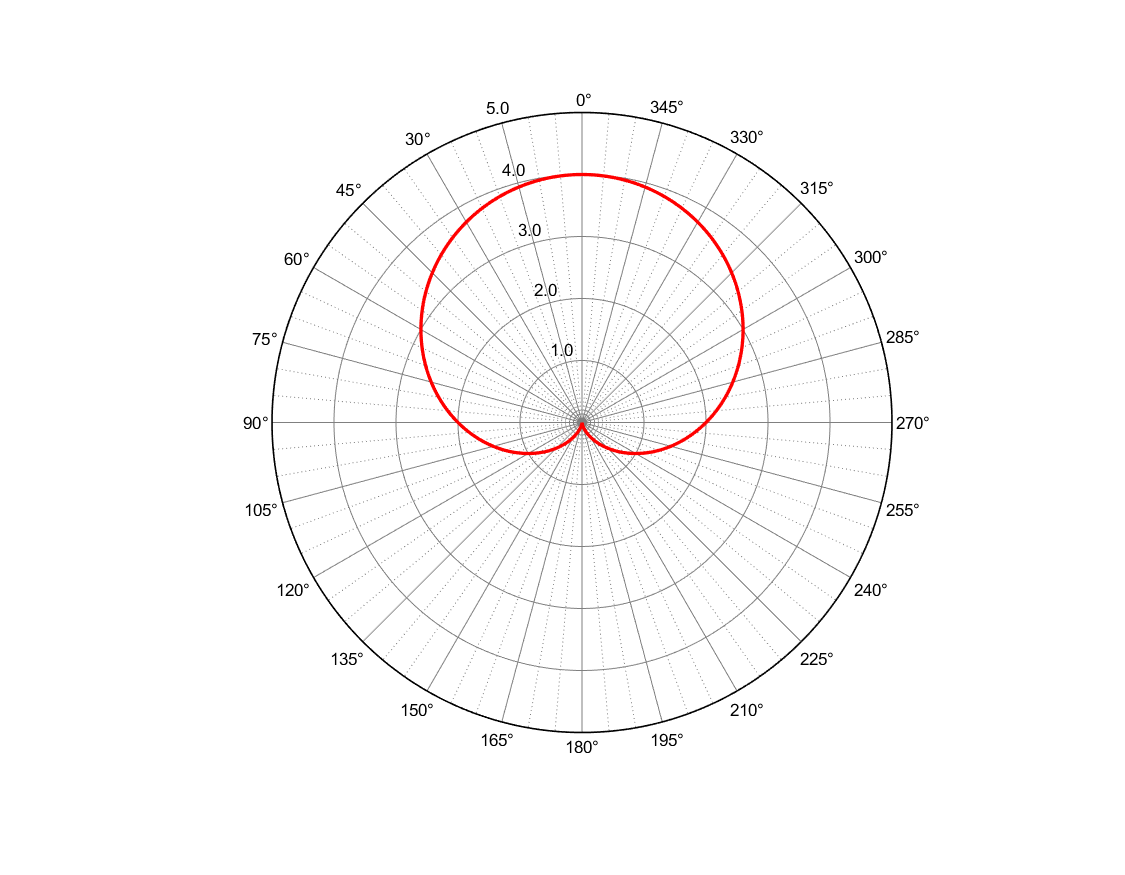

plot(px,py,'-','color','r','linewidth',2);  clear px py

## New Polar Plot Based on Old One

The output "ph" of makePolarGrid can also be used as input to create a new grid for a new plot. This is handy when making several similar plots. Other function argument-value pairs can be applied as usual and will over-ride those in the input "ph". This makes it easy to make small changes. To use this feature, simply assign the previously created "ph" to the "funArgs" argument-value pair.

The following example uses the same grid as above, but changes the location of where theta=0 starts, as well as changes to a preset labelling scheme.

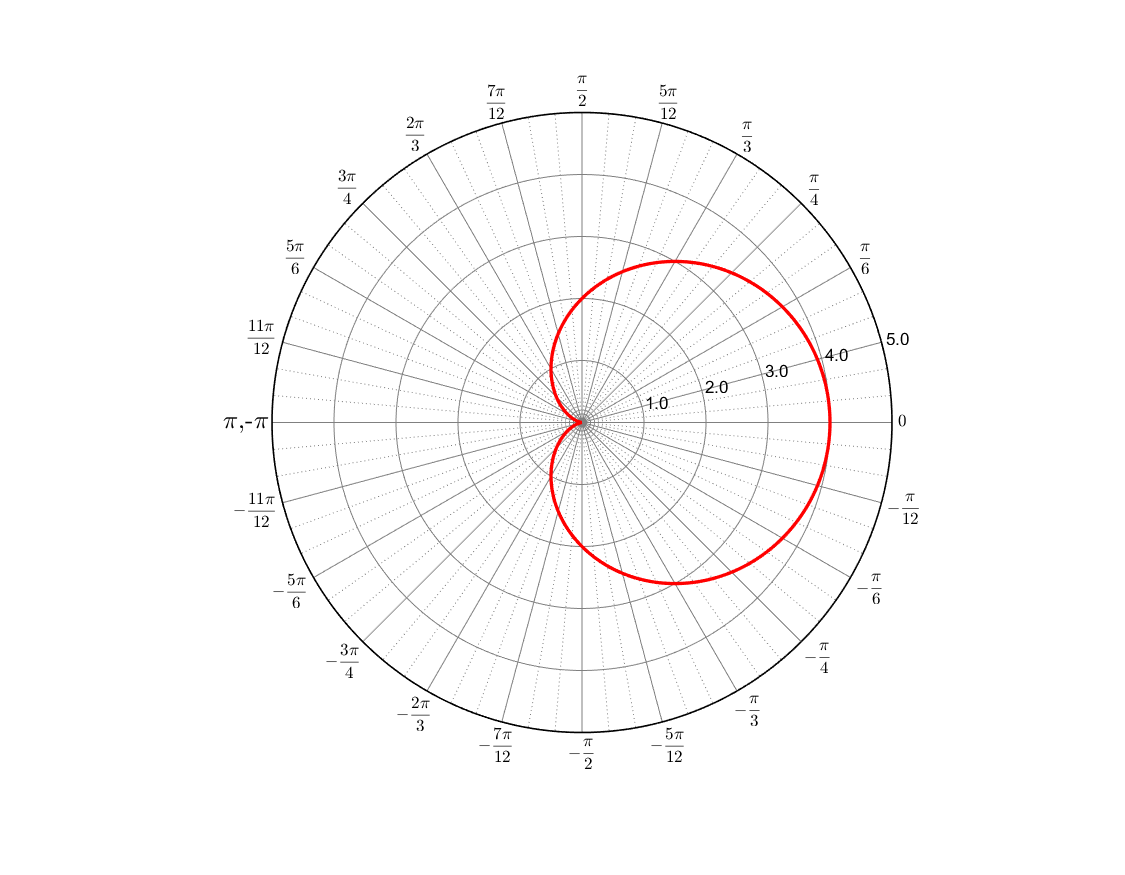

figure(2); clf

ph2 = makePolarGrid('funArgs', ph,...
    'AZeroPos', 'right',...
    'ALabelScheme', 'piA');

[px,py] = polgrid2cart(theta, r, ph2);
plot(px,py,'-','color','r','linewidth',2);  clear px py ph2

## Changes To Individual Grid Elements

The "ph" output of makePolarGrid contains handles to all of the graphics items in the grid. If some tweaks or changes are needed for individual items they can be made by calling on these handles. Note that not all the fields in ph are handles that will affect the plot, some are just the values used in the function.

The next example shows changes to spoke labels.

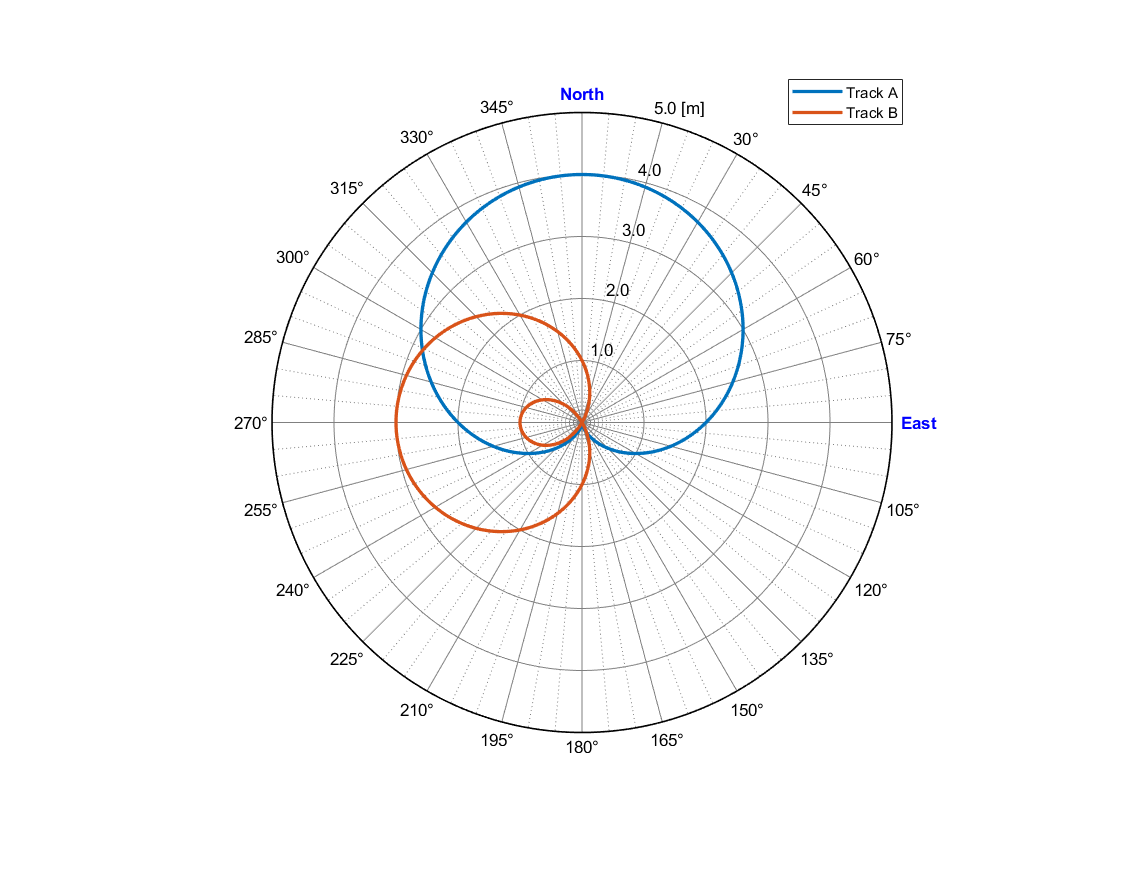

figure(3); clf

ph = makePolarGrid('RTicks',  0:1:5,...
  'RLabelFormat', '%.1f', ...
  'RUnits', '[m]');

[px,py] = polgrid2cart(theta, r, ph);
plot(px,py,'-','linewidth',2, 'displayName', 'Track A');  clear px py
hold all

[px,py] = polgrid2cart(theta, 1-2*sind(theta), ph);
plot(px,py,'-','linewidth',2, 'displayName', 'Track B');  clear px py

lh = legend;
lh.Position(1) = 0.7;
clear lh

ph.ALabels(1).String     = 'North';
ph.ALabels(1).Color      = 'b';
ph.ALabels(1).FontWeight = 'bold';
ph.ALabels(1).Position(2) = ph.ALabels(1).Position(2) +.1; % move it a bit up
ph.ALabels(7).String     = 'East'; 
ph.ALabels(7).Color      = 'b';
ph.ALabels(7).FontWeight = 'bold';
ph.ALabels(7).Position(1) = ph.ALabels(7).Position(1) +.17; % move it a bit to the right

## Polar Plot Circle Segment

It doesn't have to be a circle. Changing the ALim argument means you have the plot only cover a segment. Note that any data to be plotted that falls outside the range for the polar grid will be plotted. So this would have to be trimmed manually before hand.

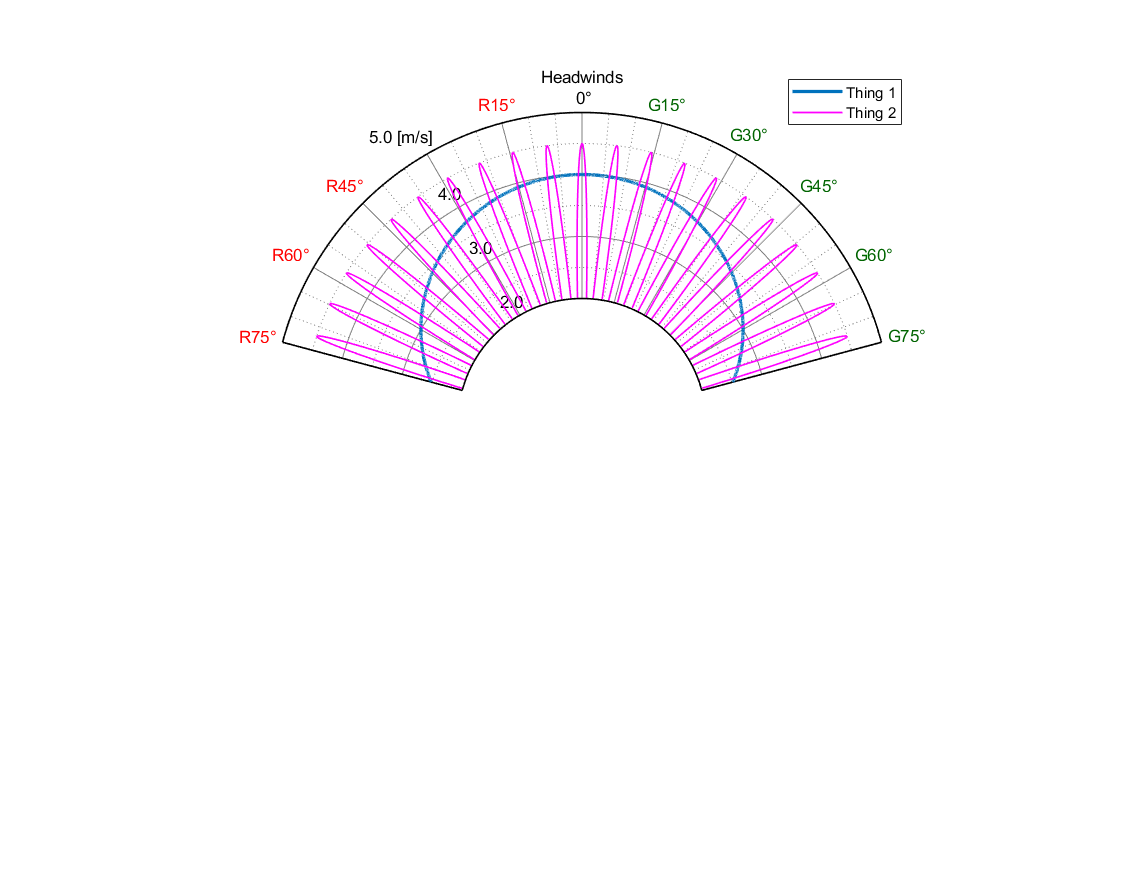

figure(4); clf

theta = 0:.01:360;
ph = makePolarGrid('ALim', [-75,75],...
  'ATicks', 15,...
  'ALabelScheme', 'wind2',... % apply custom labeling scheme
  'ADir', 'cw',...
  'RLabelAngle', -30,...
  'RTicks',  1,...
  'RLim',[2,5],...
  'RMinorTicks',0.5,...
  'RLabelFormat', '%.1f', ...
  'RUnits', '[m/s]');

% This is just another thing to plot
r = 2 + 2*cosd(theta);
r2 = 2.5-2*sind(50*theta-90);

% You will have to manually trim your data to fit within the plot limits.
idt = (theta>285 | theta<75) ;
theta(~idt) = NaN;
r(r<2 | r>5) = NaN;
r2(r2<2 | r2>5) = NaN;

[px,py] = polgrid2cart(theta, r, ph, 'trimToPlotLimits', true);
plot(px,py,'-','linewidth',2, 'displayName', 'Thing 1');  clear px py
hold all

[px,py] = polgrid2cart(theta, r2, ph, 'trimToPlotLimits', false);
plot(px,py,'-m','linewidth',1, 'displayName', 'Thing 2');  clear px py

lh = legend;
lh.Position(1) = 0.7;

## Polar Contour Plots!

How about a polar contour plot? Yes for sure!

First load in the sample data:

load exampSpec.mat

Then set up the grid, as with the previous examples:

figure(5); clf
ph = makePolarGrid(...
  'ALabelScheme', 'wave2',...
  'RTicks',        0:0.2:0.8,...  % Radial ticks (inner circles)
  'RUnits',        '[Hz]',...   % Add units to outer-most radial labels
  'RLabelFormat', '%.1f');      % Format for radial labels     


So for polar data in general, the data has to be 'closed' which means that the angular data goes all the way 0 to 360 where the data at 360 is the same as that at 0. If its not closed then the contour map will have a gap between the last angular value and 0.

For example given then 'open' angle set [0,90,180,270] then there will nothing plotted between 270 and 360. So the data at 0 has to be copied to 360 to close the set.

The example data was given as closed data but just to show how to close data in general, the following if-block that will check for you and convert open to closed if needed.

if ~mod((exampSpec.dir(1) - exampSpec.dir(end)), 360)
   exampSpec.dir(end+1) = exampSpec.dir(1) + 360;
   exampSpec.spec(:,end+1) = exampSpec.spec(:,1);    
end

The example data has the radial (freq) and angular (dir) data as column vectors. So first need to meshgrid them as you would for a regular contour plot

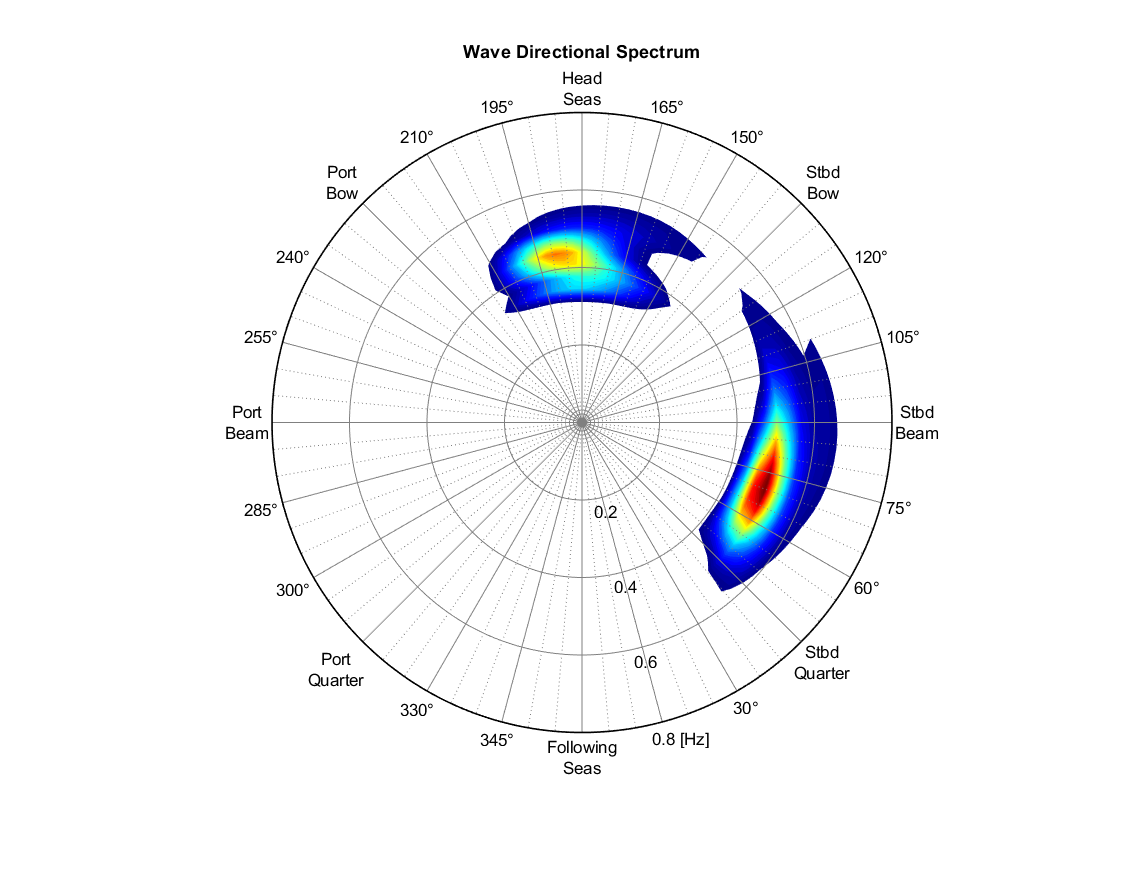

[md,mf] = meshgrid(exampSpec.dir, exampSpec.freq);

% Now convert to cartesian coords
[px,py] = polgrid2cart(md, mf, ph);

% And then use contourf to plot. Optional formatting adjustments follow.
[~,hc]  = contourf(px, py, exampSpec.spec, 50);
uistack(hc, 'bottom');  % this will put the grid on top of the contours
hc.LevelList(1:5) = [];    % this removes the countours on lowest level(s) 
hc.LineStyle = 'none';  % enable/disble contour lines
colormap jet
title('Wave Directional Spectrum')